% Tensor Component Analysis (TCA): via Canonical Polyadic Decomposition
% (CPD) - Factor Analysis
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLT';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

condition = ['BLT'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLTAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



cpd_input_path = fullfile(output_path,condition);

U_pre = load(fullfile(cpd_input_path,"Bos2_U_pre.mat")).U_pre;
U_post = load(fullfile(cpd_input_path,"Bos2_U_post.mat")).U_post;


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

% data = EEG.data(:, :, epoch_trials);
% 
% % Bandpass filter beta band (13-30 Hz)
% beta_band = [13 30];
% beta_signal = zeros(size(data)); % Preallocate
% for epoch = 1:size(data, 3)
%     beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
% end
% 
% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

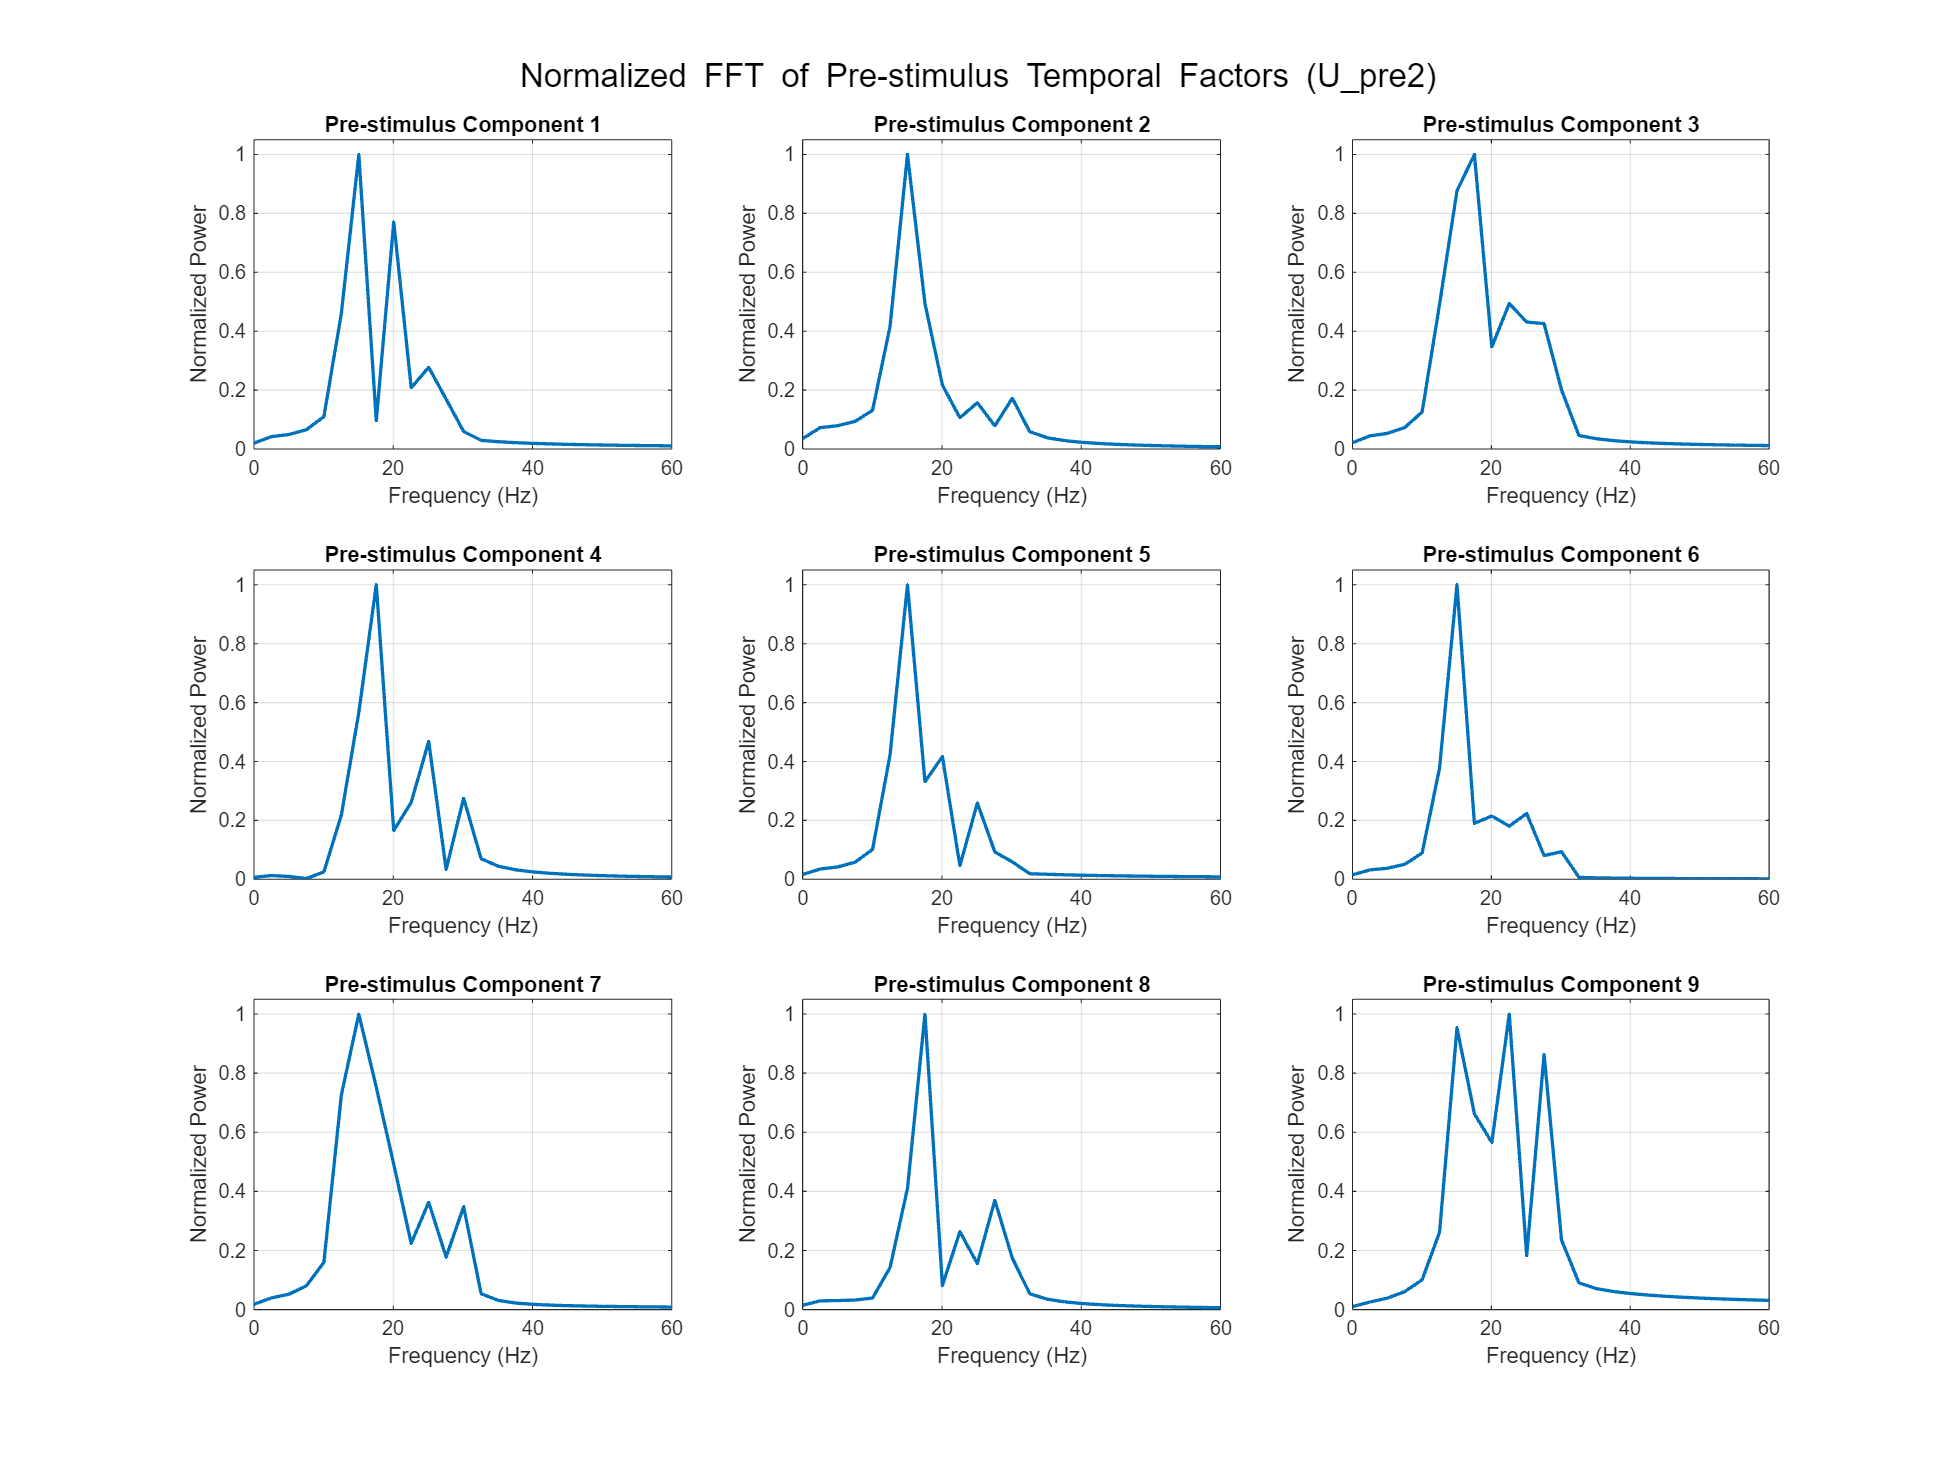

% Temporal factor analysis: FFT
% FFT analysis on temporal factors with normalization

% Define parameters for FFT
sampling_rate = fs; % Use your original sampling rate from EEG data
time_pre = time_vector(pre_idx);
time_post = time_vector(post_idx);
dt_pre = mean(diff(time_pre)); % Time step for pre-stimulus
dt_post = mean(diff(time_post)); % Time step for post-stimulus

% Calculate frequency axis
N_pre = length(time_pre);
freq_pre = (0:N_pre-1)/(N_pre*dt_pre); % Frequency axis in Hz
freq_pre = freq_pre(1:floor(N_pre/2)+1); % Keep only positive frequencies

N_post = length(time_post);
freq_post = (0:N_post-1)/(N_post*dt_post); % Frequency axis in Hz
freq_post = freq_post(1:floor(N_post/2)+1); % Keep only positive frequencies

% Preallocate arrays to store power spectra for normalization
pre_power_spectra = zeros(length(freq_pre), 9);
post_power_spectra = zeros(length(freq_post), 9);

% Compute FFT for all pre-stimulus components
for comp = 1:9
    signal = U_pre{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_pre);
    P1 = P2(1:floor(N_pre/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    pre_power_spectra(:, comp) = P1;
end

% Compute FFT for all post-stimulus components
for comp = 1:9
    signal = U_post{2}(:, comp);
    Y = fft(signal);
    P2 = abs(Y/N_post);
    P1 = P2(1:floor(N_post/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    post_power_spectra(:, comp) = P1;
end

% Normalize each power spectrum by its maximum value
for comp = 1:9
    pre_power_spectra(:, comp) = pre_power_spectra(:, comp) / max(pre_power_spectra(:, comp));
    post_power_spectra(:, comp) = post_power_spectra(:, comp) / max(post_power_spectra(:, comp));
end

% Create figures for pre-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_pre, pre_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Pre-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_pre))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Pre-stimulus Temporal Factors (U\_pre{2})');

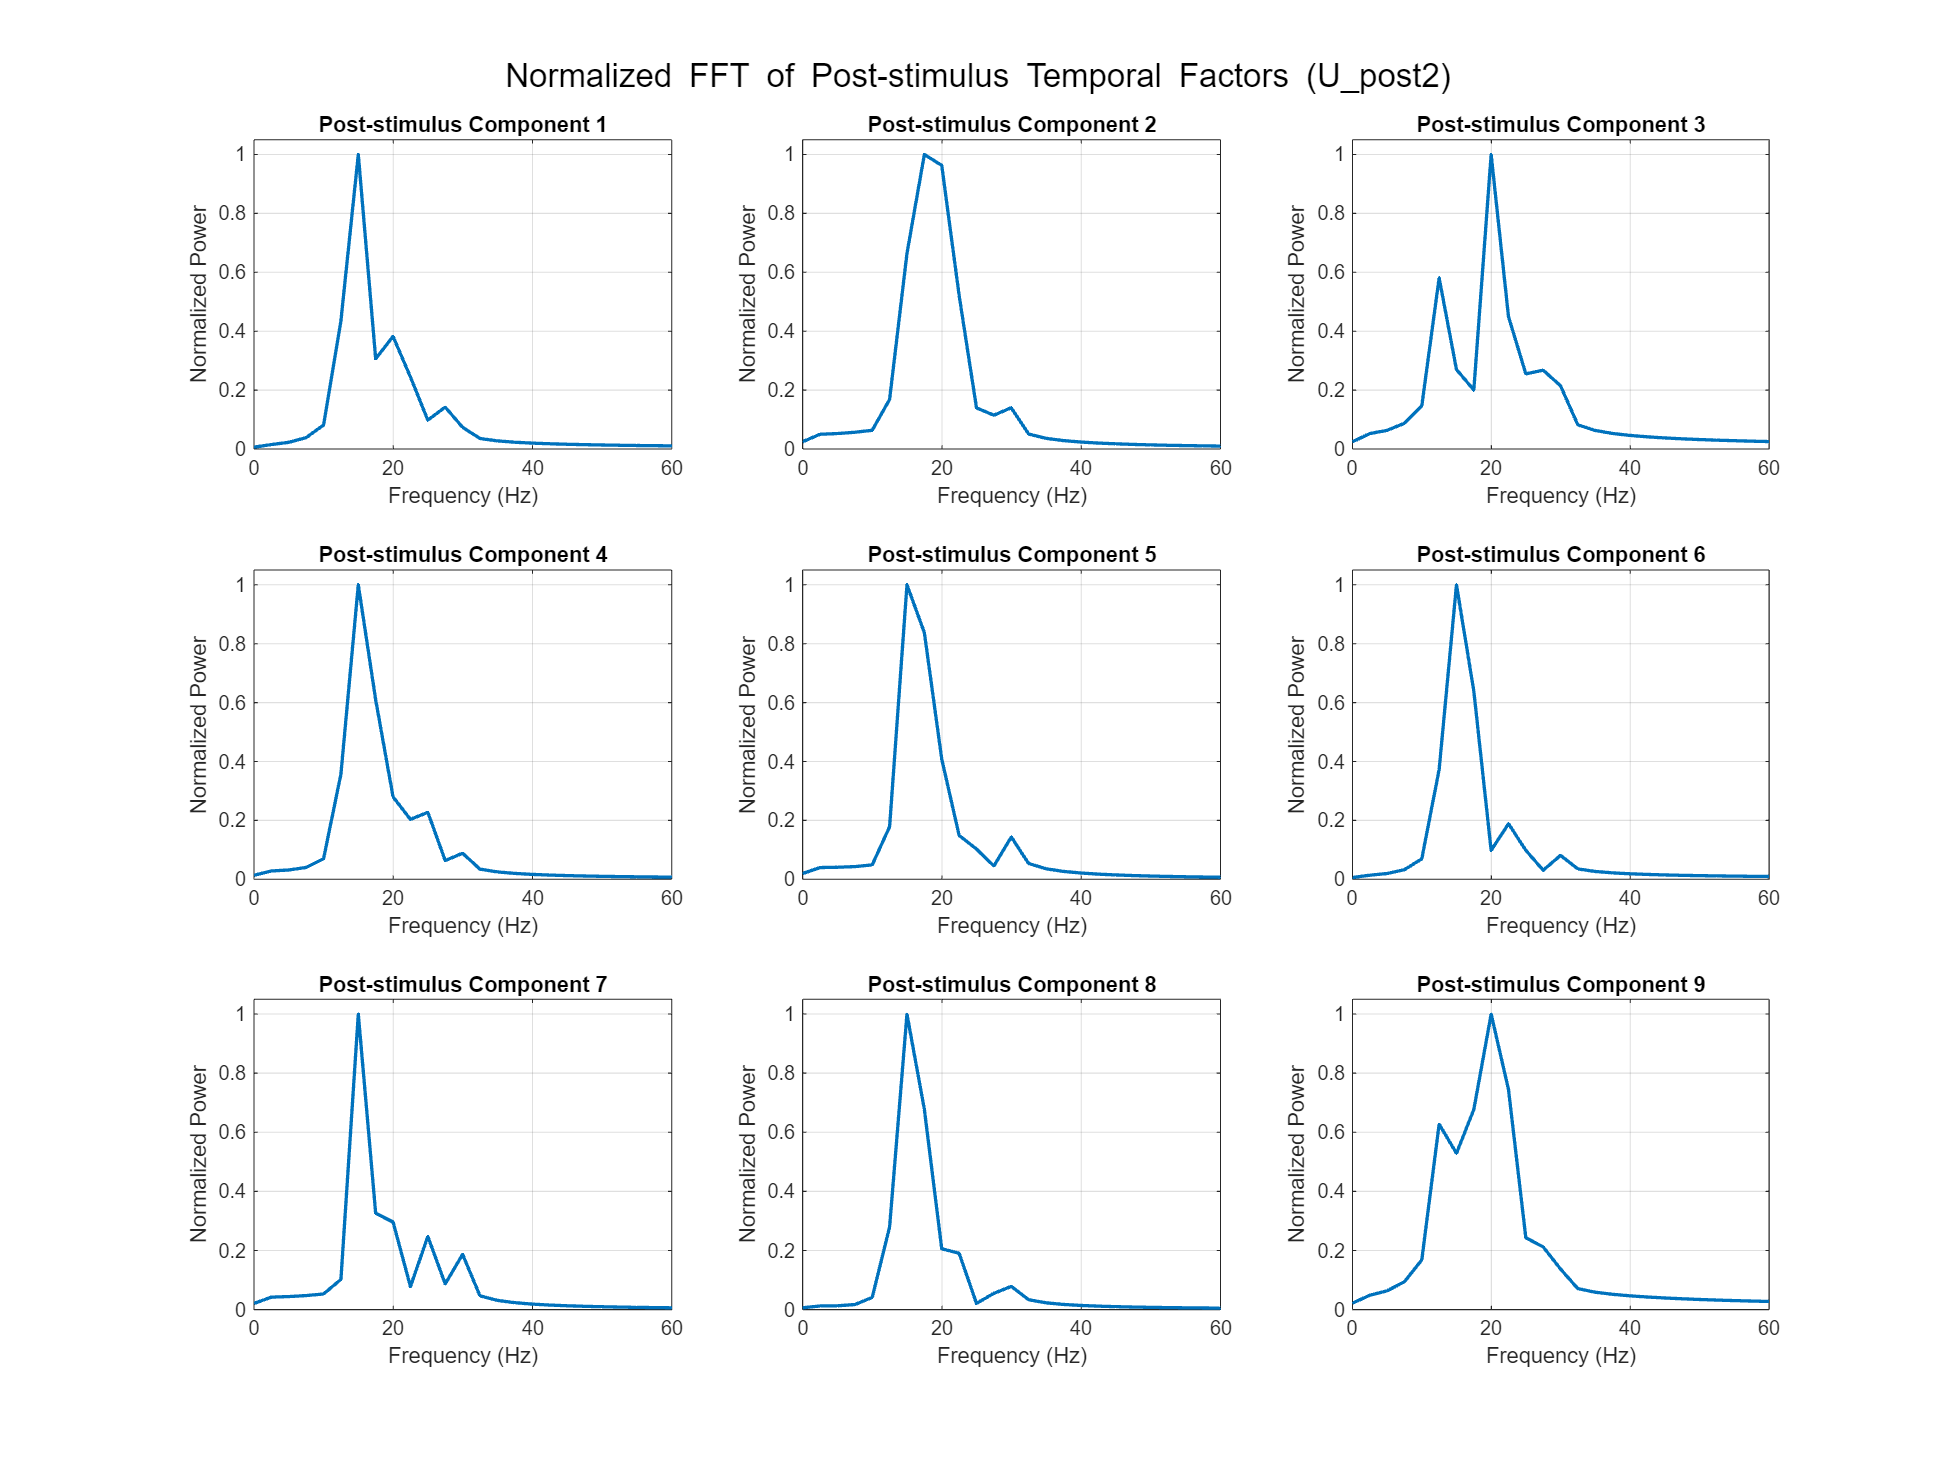


% Create figures for post-stimulus components with normalized power
figure('Position', [100, 100, 1200, 900]);
for comp = 1:9
    subplot(3, 3, comp);
    plot(freq_post, post_power_spectra(:, comp), 'LineWidth', 1.5);
    grid on;
    title(['Post-stimulus Component ', num2str(comp)]);
    xlabel('Frequency (Hz)');
    ylabel('Normalized Power');
    xlim([0, min(60, max(freq_post))]);
    ylim([0, 1.05]); % Set y-axis limit to be consistent
end
sgtitle('Normalized FFT of Post-stimulus Temporal Factors (U\_post{2})');

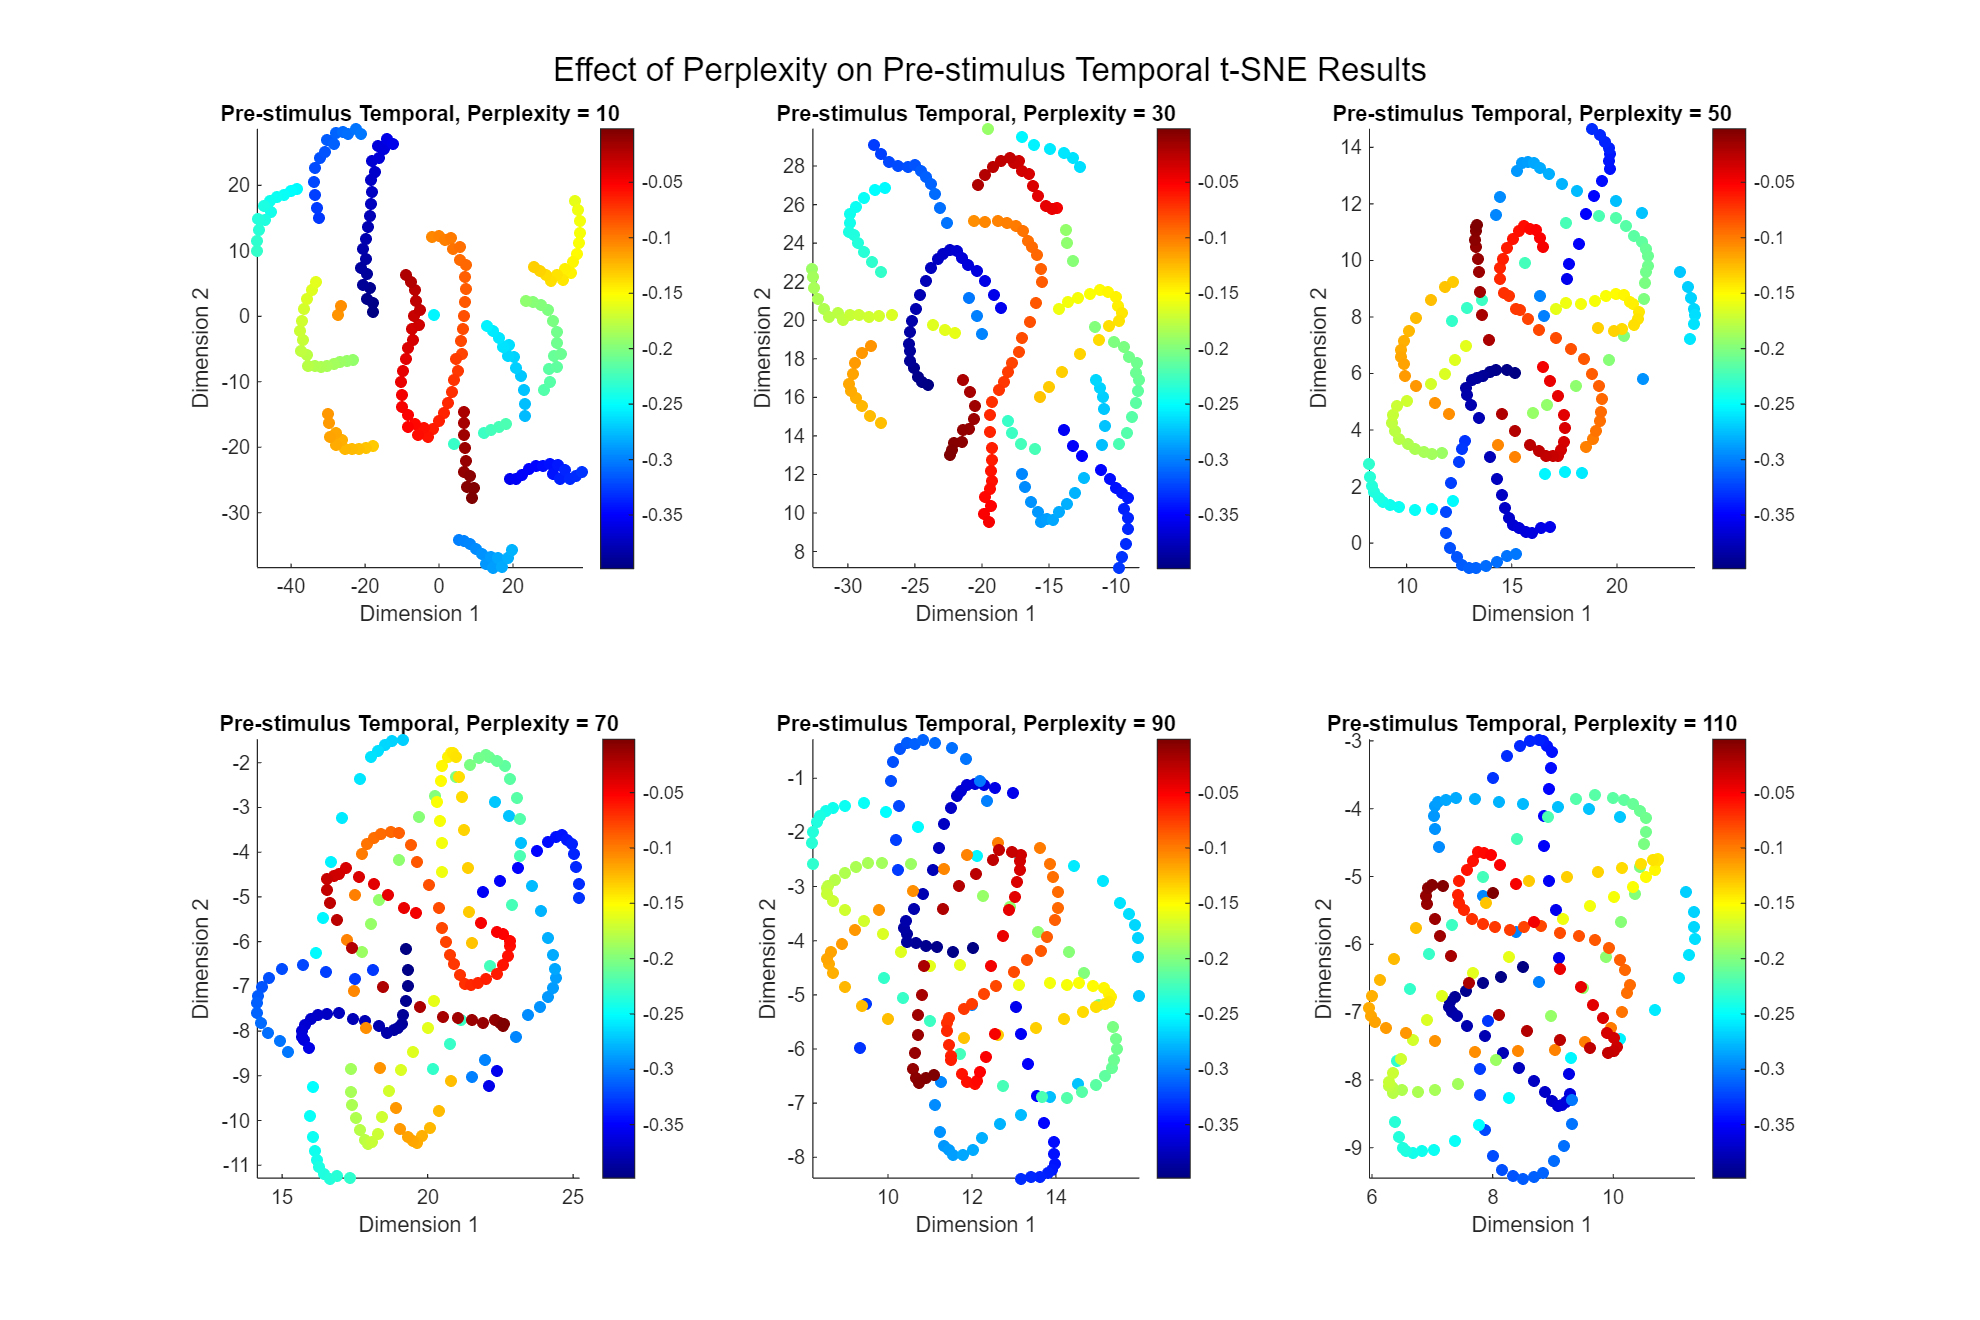

% Systematic approach to selecting perplexity for temporal factors
perplexity_values = [10, 30, 50, 70, 90, 110];
num_dims = 2;  % Using 2D for easier comparison

% Prepare temporal factors
temporal_factors_pre = U_pre{2};  % Time points × components
temporal_factors_post = U_post{2};  % Time points × components

% Preallocate cell arrays to store results
Y_pre_temporal_results = cell(length(perplexity_values), 1);
Y_post_temporal_results = cell(length(perplexity_values), 1);

% Run t-SNE with different perplexity values
for i = 1:length(perplexity_values)
    perp = perplexity_values(i);
    
    % Pre-stimulus
    effective_perp_pre = min(perp, size(temporal_factors_pre, 1)-1);
    Y_pre_temporal_results{i} = tsne(temporal_factors_pre, 'Perplexity', effective_perp_pre, 'NumDimensions', num_dims);
    
    % Post-stimulus
    effective_perp_post = min(perp, size(temporal_factors_post, 1)-1);
    Y_post_temporal_results{i} = tsne(temporal_factors_post, 'Perplexity', effective_perp_post, 'NumDimensions', num_dims);
end

% Create a grid of plots for pre-stimulus temporal results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Color points by time
    scatter(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 30, time_vector(pre_idx), 'filled');
    title(['Pre-stimulus Temporal, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;
end
sgtitle('Effect of Perplexity on Pre-stimulus Temporal t-SNE Results');

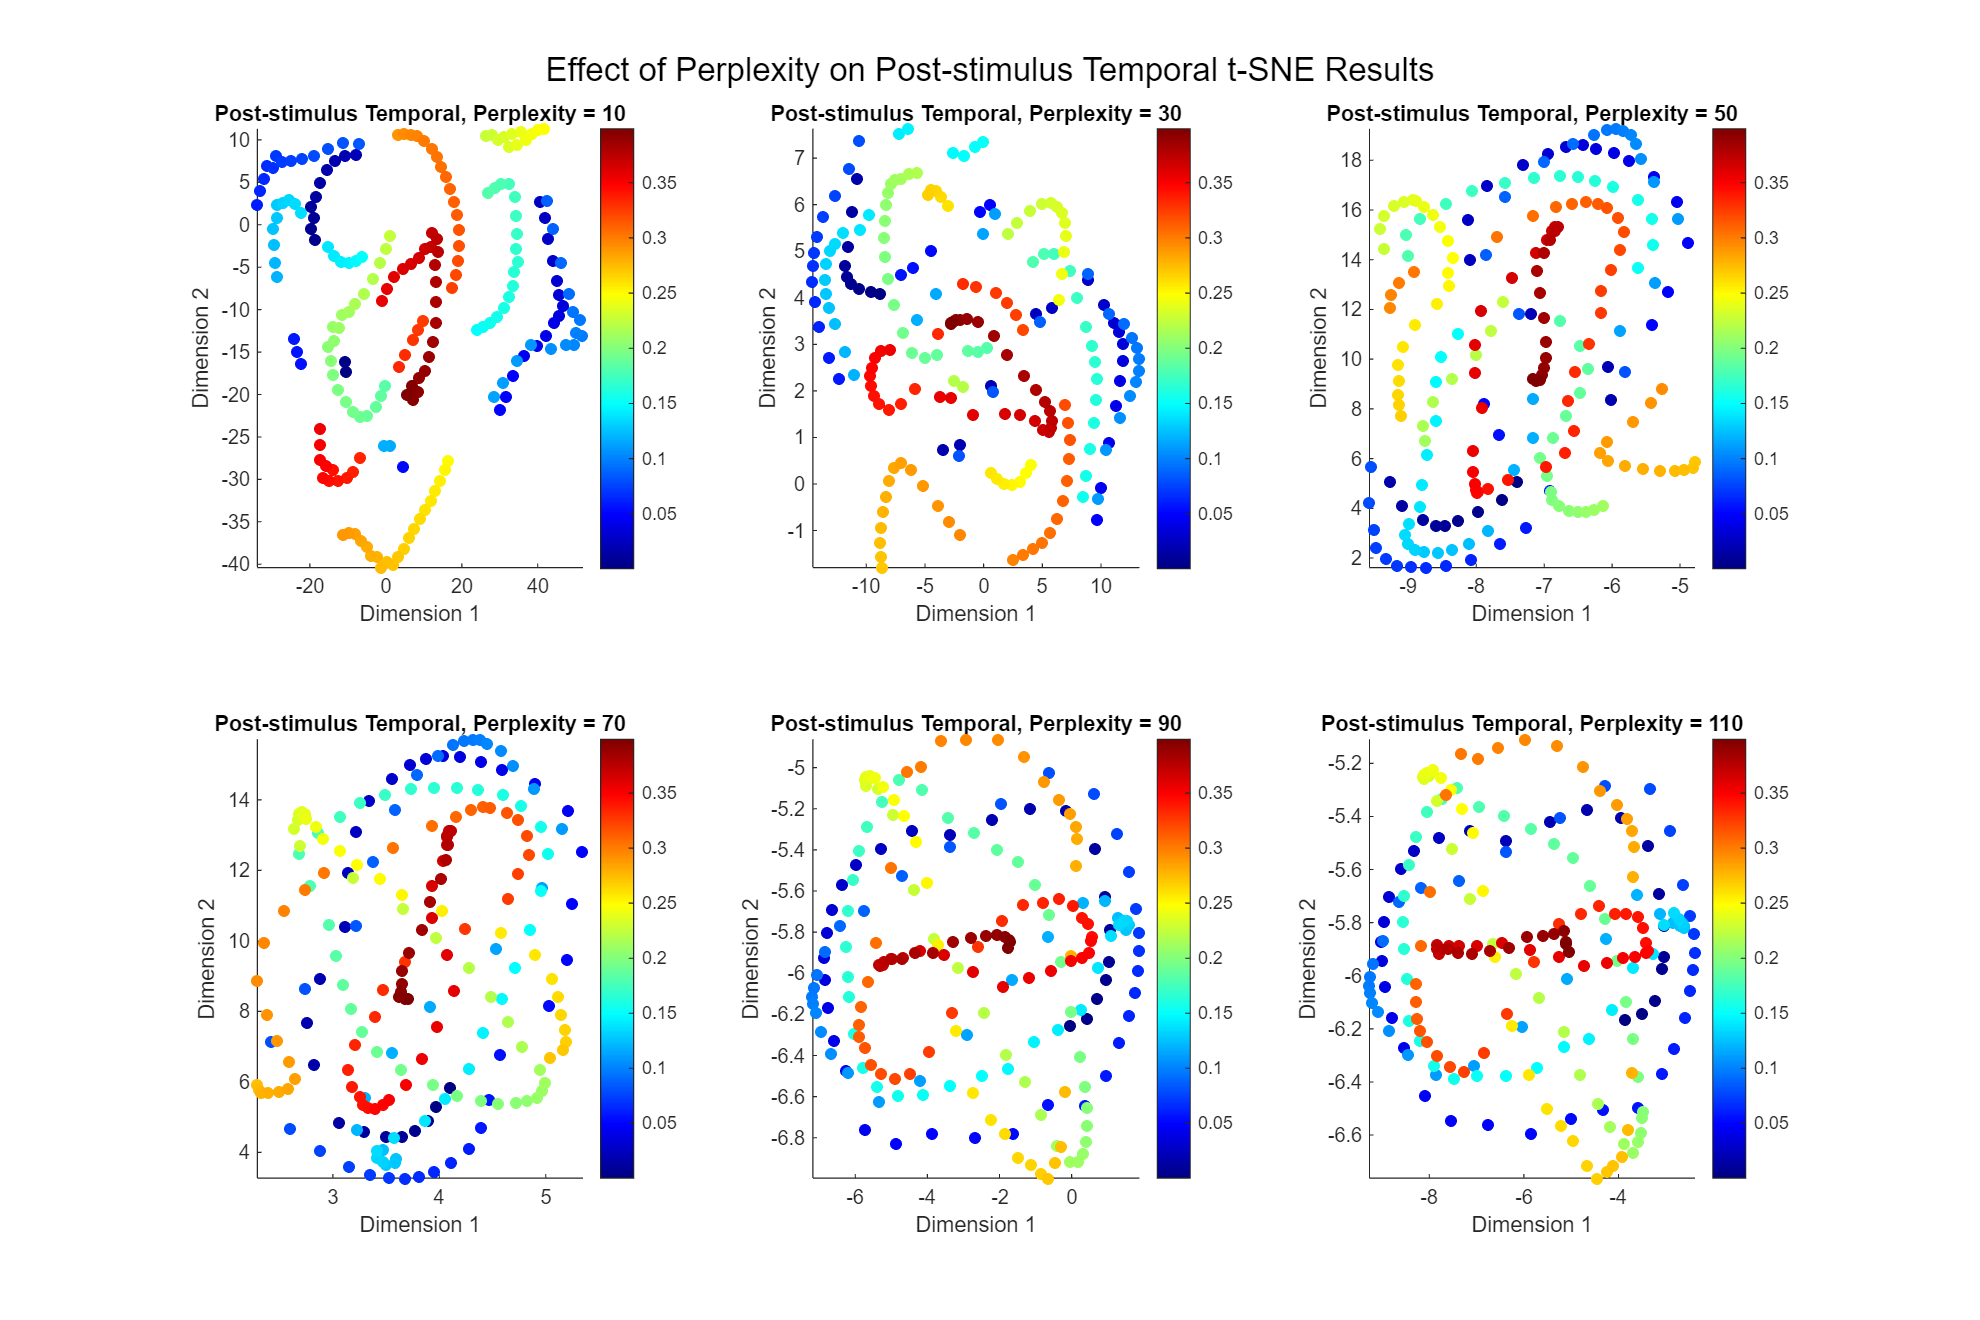


% Create a grid of plots for post-stimulus temporal results
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Color points by time
    scatter(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 30, time_vector(post_idx), 'filled');
    title(['Post-stimulus Temporal, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;
end
sgtitle('Effect of Perplexity on Post-stimulus Temporal t-SNE Results');

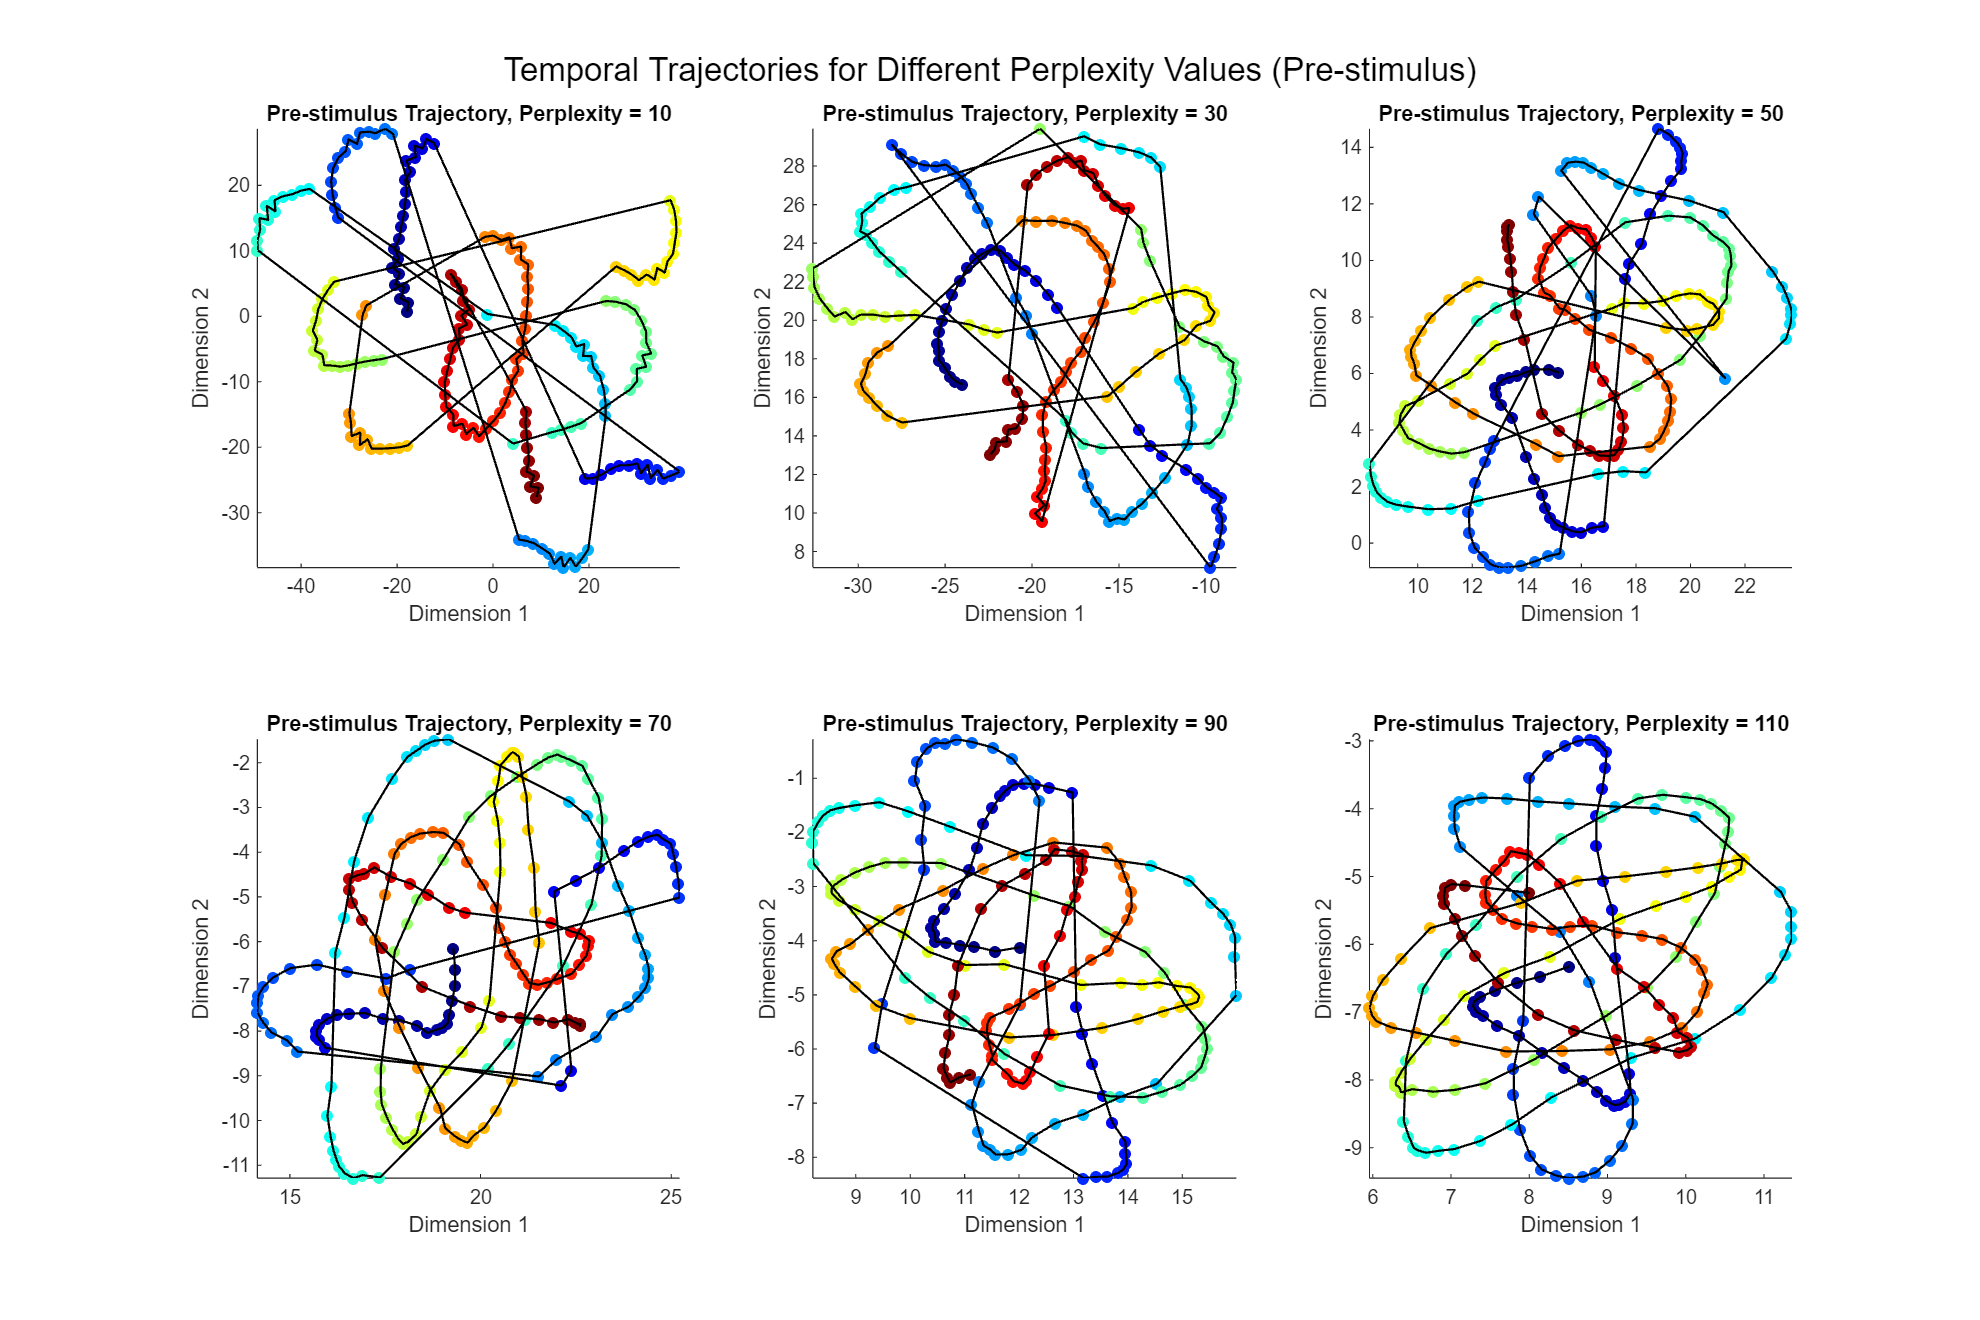


% Add trajectory plots for different perplexity values
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    % Plot points colored by time
    scatter(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 30, time_vector(pre_idx), 'filled');
    hold on;
    % Add connecting line to show trajectory
    plot(Y_pre_temporal_results{i}(:,1), Y_pre_temporal_results{i}(:,2), 'k-', 'LineWidth', 1);
    title(['Pre-stimulus Trajectory, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
    hold off;
end
sgtitle('Temporal Trajectories for Different Perplexity Values (Pre-stimulus)');

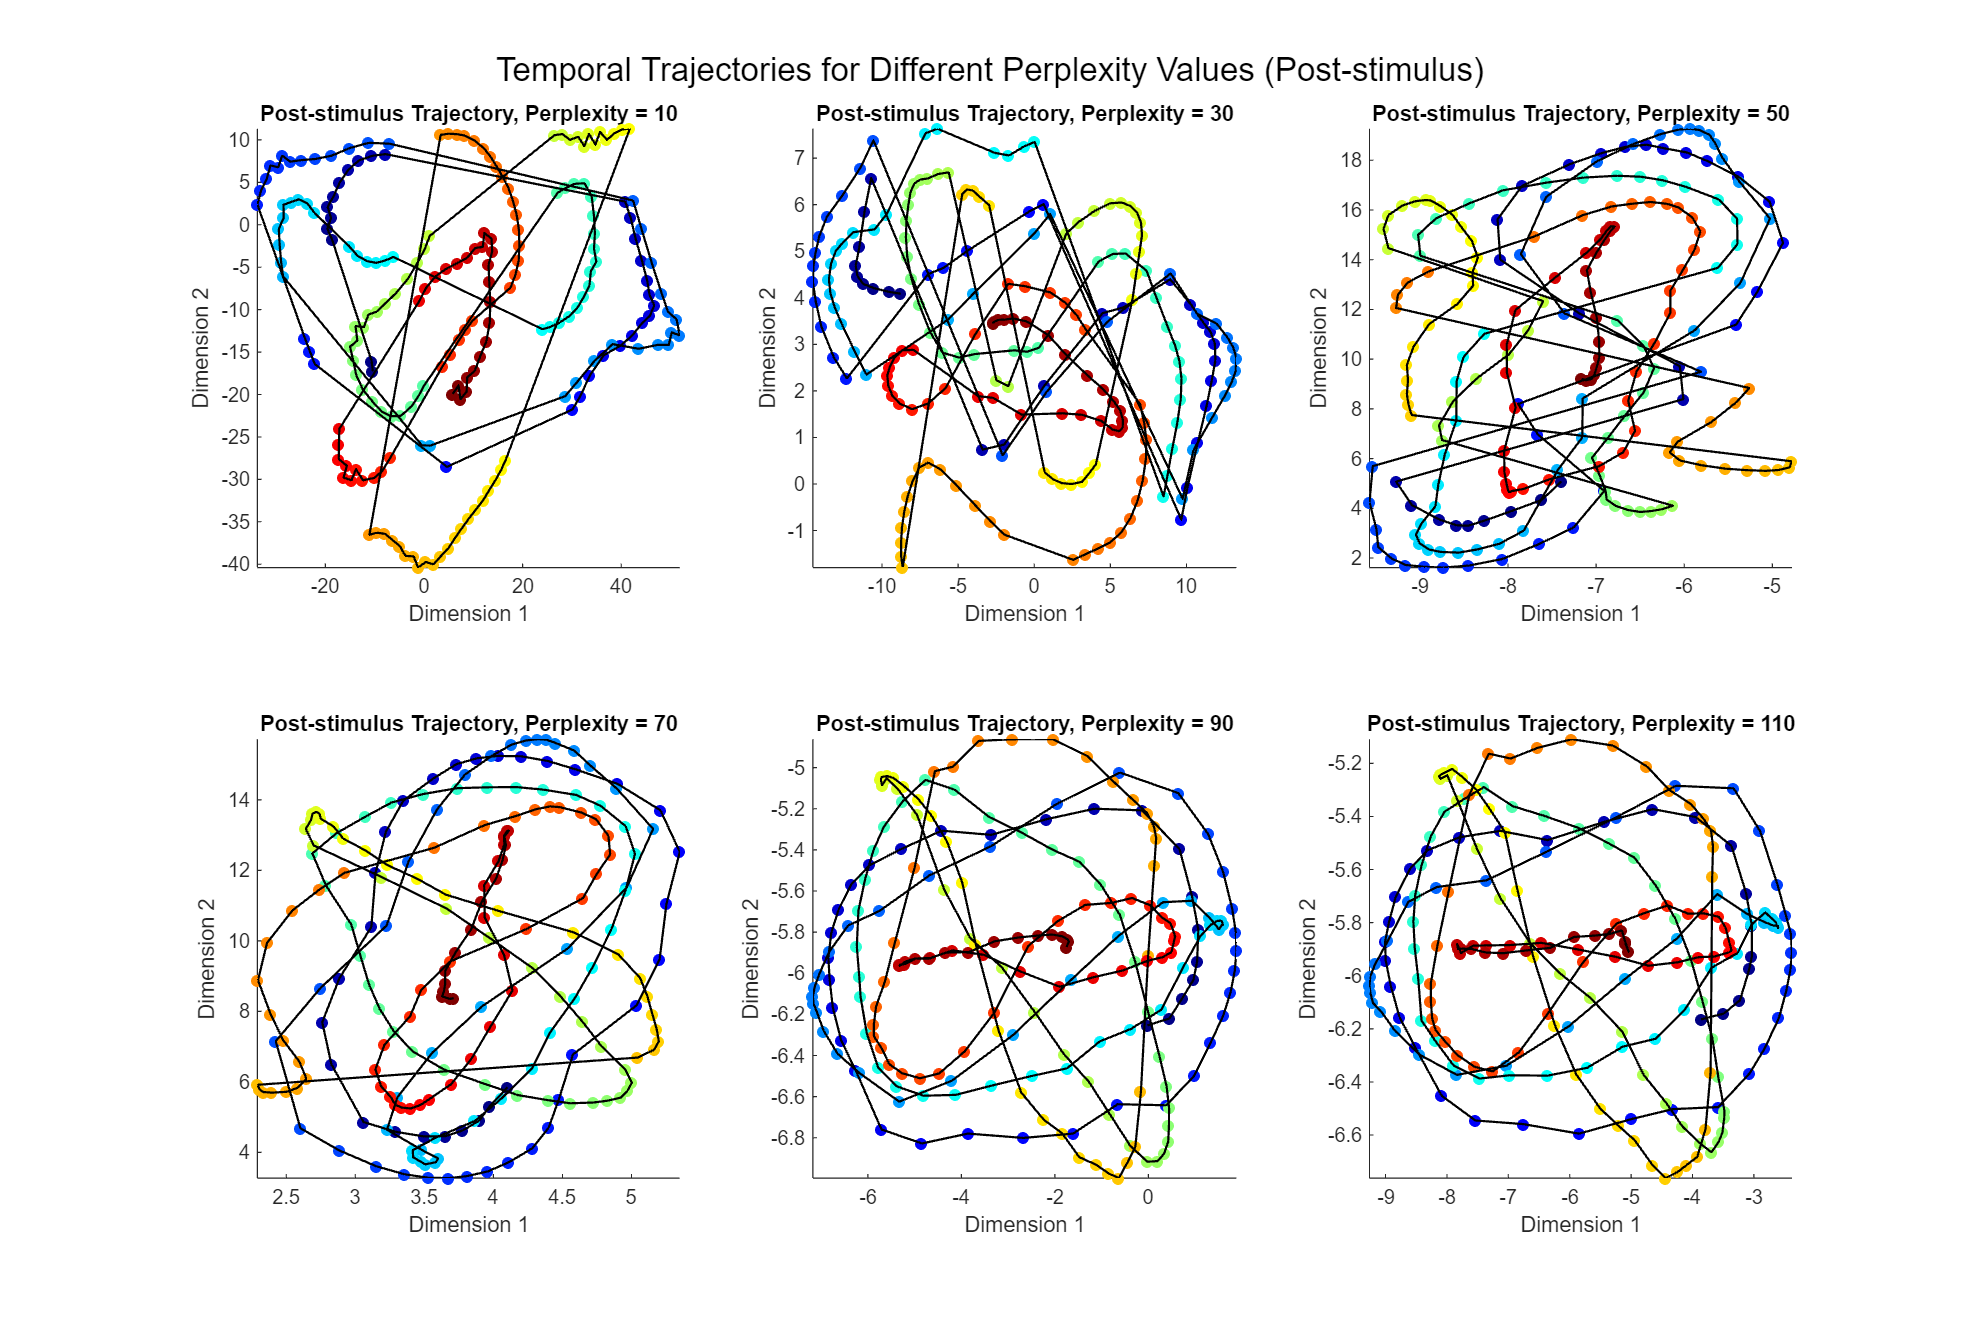


% Same for post-stimulus trajectories
figure('Position', [100, 100, 1200, 800]);
for i = 1:length(perplexity_values)
    subplot(2, 3, i);
    scatter(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 30, time_vector(post_idx), 'filled');
    hold on;
    plot(Y_post_temporal_results{i}(:,1), Y_post_temporal_results{i}(:,2), 'k-', 'LineWidth', 1);
    title(['Post-stimulus Trajectory, Perplexity = ', num2str(perplexity_values(i))]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    axis tight;
    hold off;
end
sgtitle('Temporal Trajectories for Different Perplexity Values (Post-stimulus)');

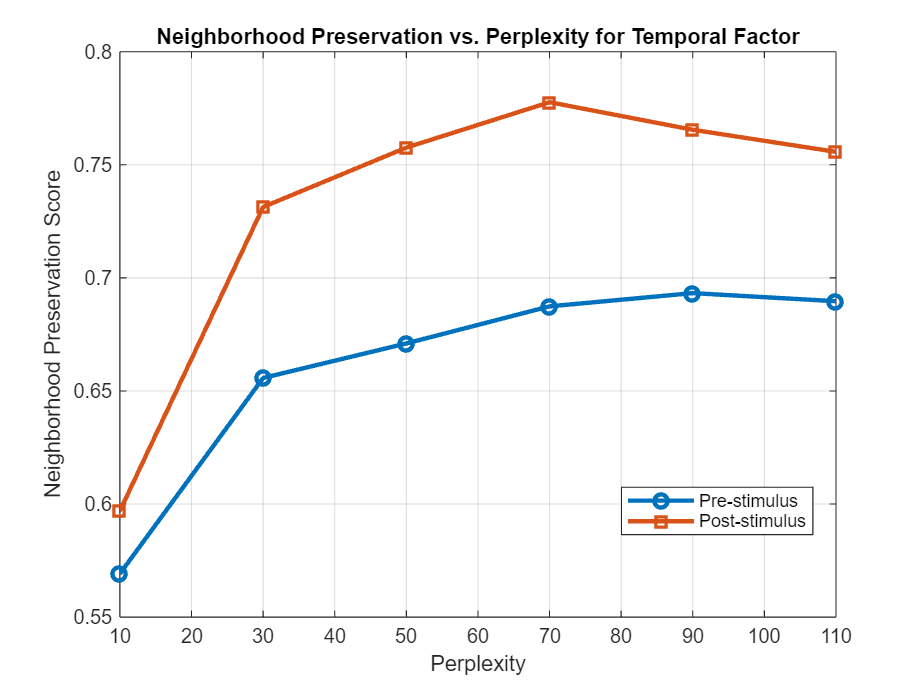

% A simpler approach: evaluate local neighborhood preservation
k_neighbors_time = 26; % Number of neighbors to consider
% Calculate neighborhood preservation for each perplexity
neighborhood_scores_time_pre = zeros(length(perplexity_values), 1);
neighborhood_scores_time_post = zeros(length(perplexity_values), 1);

for i = 1:length(perplexity_values)
    neighborhood_scores_time_pre(i) = calculate_neighborhood_preservation(temporal_factors_pre, Y_pre_temporal_results{i}, k_neighbors_time);
    neighborhood_scores_time_post(i) = calculate_neighborhood_preservation(temporal_factors_post, Y_post_temporal_results{i}, k_neighbors_time);
end

% Plot neighborhood preservation scores
figure;
plot(perplexity_values, neighborhood_scores_time_pre, 'o-', 'LineWidth', 2, 'DisplayName', 'Pre-stimulus');
hold on;
plot(perplexity_values, neighborhood_scores_time_post, 's-', 'LineWidth', 2, 'DisplayName', 'Post-stimulus');
xlabel('Perplexity');
ylabel('Neighborhood Preservation Score');
title('Neighborhood Preservation vs. Perplexity for Temporal Factor');
legend('Location', 'best');
grid on;

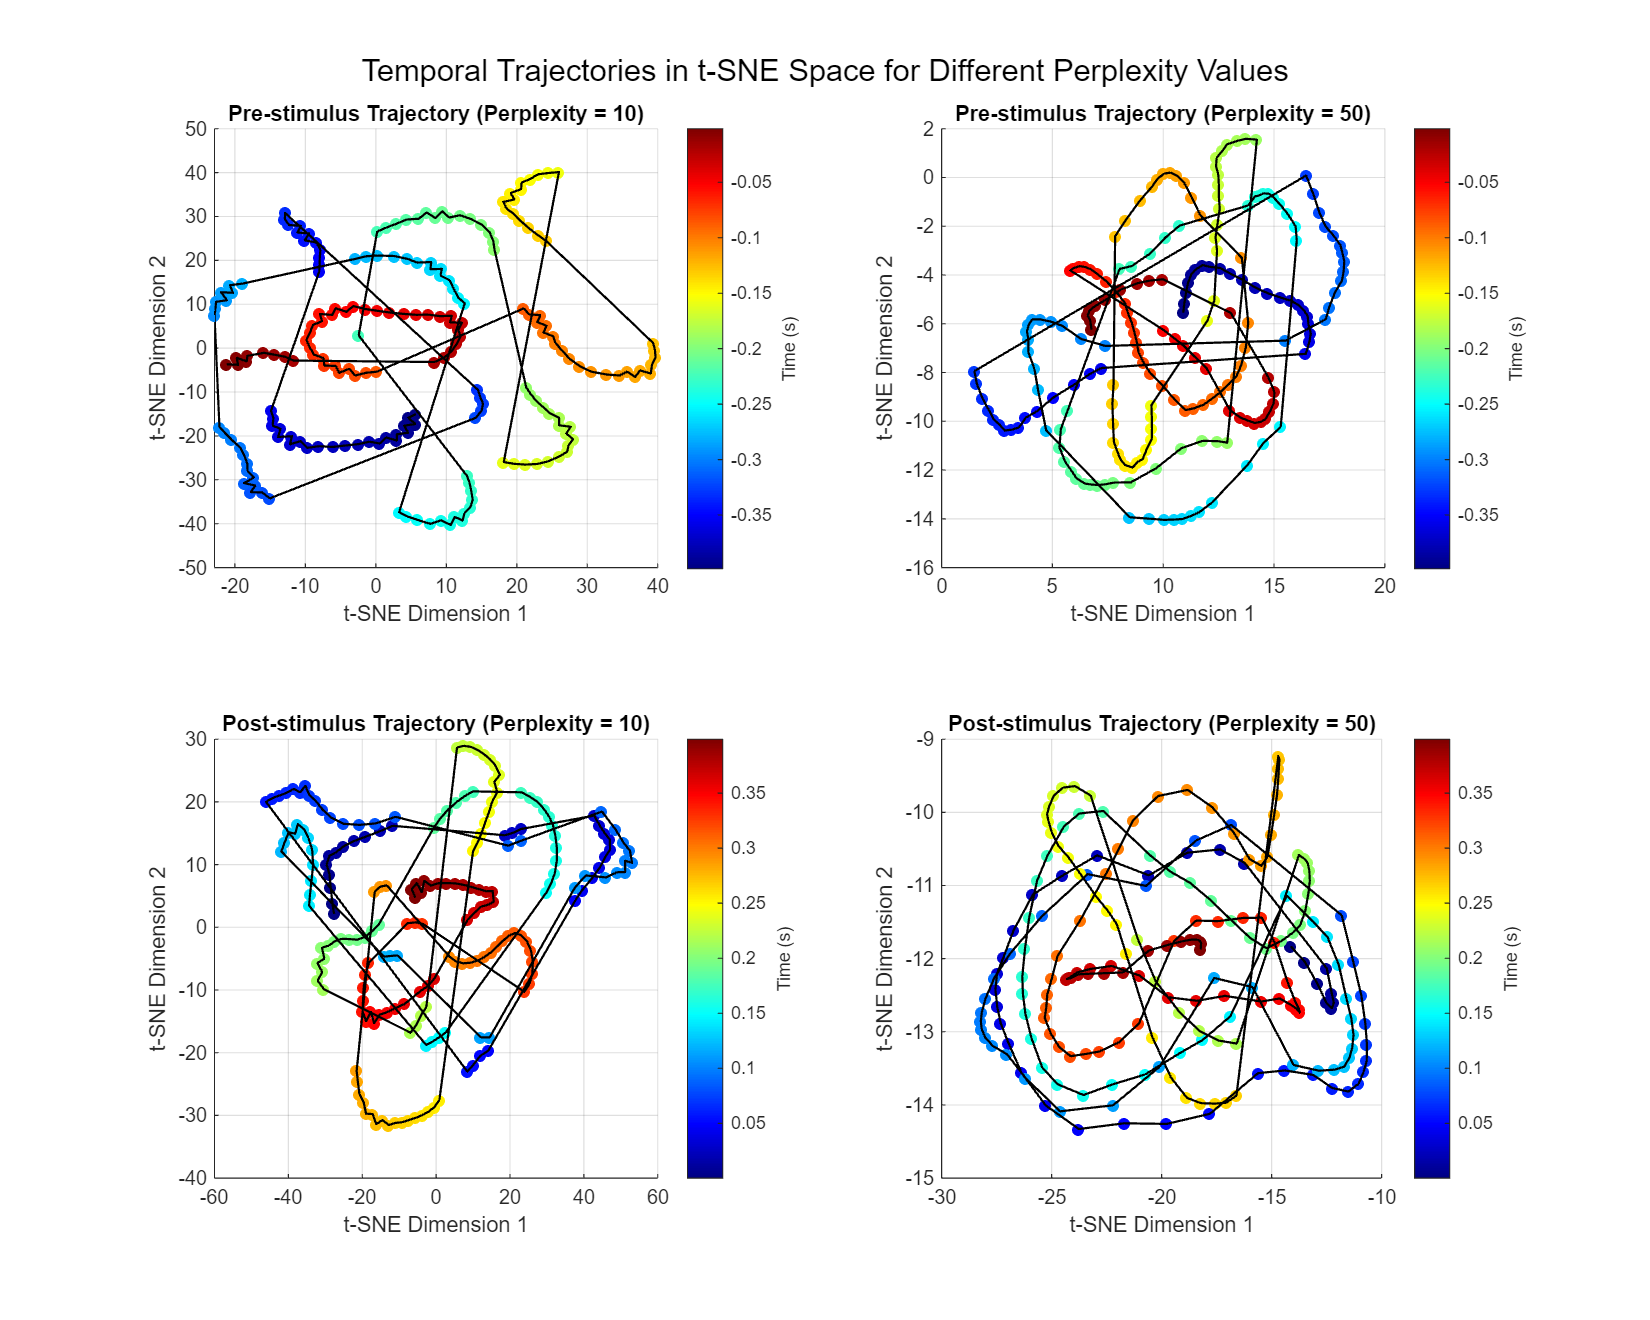

% Parameters for t-SNE
perplexity_values = [10, 50]; % Two different perplexity values
num_dims = 2;    % 2D visualization 

% Create a figure with 2x2 subplots
figure('Position', [100, 100, 1000, 800]);

% Run t-SNE for each perplexity value
for p = 1:length(perplexity_values)
    perplexity = perplexity_values(p);
    
    % t-SNE for pre-stimulus temporal factors
    temporal_factors_pre = U_pre{2}; % Already in the right format (time points × components)
    Y_pre_temporal = tsne(temporal_factors_pre, 'Perplexity', min(perplexity, size(temporal_factors_pre, 1)-1), 'NumDimensions', num_dims);
    
    % t-SNE for post-stimulus temporal factors
    temporal_factors_post = U_post{2}; % Already in the right format (time points × components)
    Y_post_temporal = tsne(temporal_factors_post, 'Perplexity', min(perplexity, size(temporal_factors_post, 1)-1), 'NumDimensions', num_dims);
    
    % Plot pre-stimulus temporal trajectory (top row)
    subplot(2, 2, p);
    scatter(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 30, time_vector(pre_idx), 'filled');
    hold on;
    plot(Y_pre_temporal(:,1), Y_pre_temporal(:,2), 'k-', 'LineWidth', 1);
    colormap(jet);
    c = colorbar;
    c.Label.String = 'Time (s)';
    title(sprintf('Pre-stimulus Trajectory (Perplexity = %d)', perplexity));
    xlabel('t-SNE Dimension 1');
    ylabel('t-SNE Dimension 2');
    grid on;
    
    % Plot post-stimulus temporal trajectory (bottom row)
    subplot(2, 2, p+2);
    scatter(Y_post_temporal(:,1), Y_post_temporal(:,2), 30, time_vector(post_idx), 'filled');
    hold on;
    plot(Y_post_temporal(:,1), Y_post_temporal(:,2), 'k-', 'LineWidth', 1);
    colormap(jet);
    c = colorbar;
    c.Label.String = 'Time (s)';
    title(sprintf('Post-stimulus Trajectory (Perplexity = %d)', perplexity));
    xlabel('t-SNE Dimension 1');
    ylabel('t-SNE Dimension 2');
    grid on;
end

% Add a main title to the figure
sgtitle('Temporal Trajectories in t-SNE Space for Different Perplexity Values', 'FontSize', 14);

Testing n_neighbors=15, min_dist=0.10 (1/

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)


min=-11.50, max=1.50
mins:	-2.0199     -2.2691     -2.8375     -2.4189     -3.2065     -1.9791     -0.9347      -1.819    -0.69482     -1.3984     -2.3479     -1.2754     -1.8753      -3.062     -1.9341     -1.8228     -3.5221     -1.0555     -1.1375     -3.5232    -0.72901     -1.3041     -1.2105    -0.86193     -4.2797     -2.7543     -2.6582     -1.3199     -2.2006       -2.12     -4.6039     -1.5133     -1.5569     -1.0359     -2.3997     -1.9782    -0.93541     -1.0046     -2.8748     -1.4384      -2.899     -1.4875     -2.5471
maxs:	2.5089      2.2672      3.1392      2.9067      3.7596       1.676      1.1558      1.8232        0.68       1.456      2.3937       1.284      1.9071      2.6549      2.0394       1.699      3.7728       1.317     0.94783      4.3008     0.81351       1.787      1.0419     0.94307      4.0292      2.6147       2.047      1.1602      2.4258      2.3236       5.194      1.5308      1.4362     0.99339      2.3948      1.8252      1.0372     0.96706     

ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0127 0.0184 0.0231 0.0277 0.0320 0.0363 0.0410 0.0463 0.0519 0.0723]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


UMAP reduction finished (cost 1.60 secs)
 Finished basic (ub) reduction


UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan



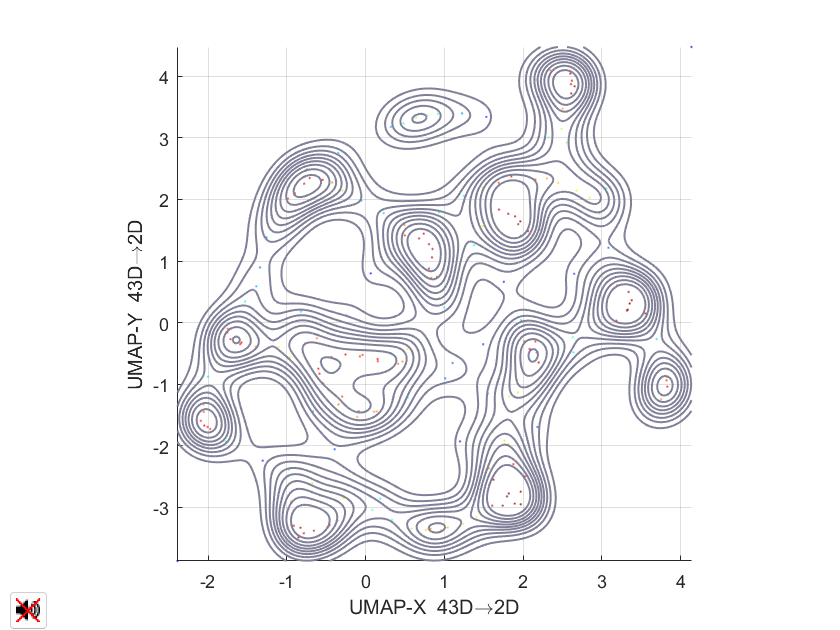


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 24 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)


min=-11.50, max=1.50
mins:	-3.26854     -2.01247     -1.60953     -3.67395     -6.36825     -8.96502     -1.69065     -3.37712     -1.30074     -3.22186      -2.1933     -1.19368     -3.92441     -3.93531     -3.57254     -11.1836     -1.76507      -2.5523     -7.71056     -1.23129     -1.98247     -8.07909     -1.13195     -1.45566     -2.25568    -0.640378     -1.03413     -1.49313     -1.80352     -4.50602      -3.0168     -3.26345     -1.22715     -2.93917     -2.01004     -1.70077     -1.02392     -2.46569    -0.726884     -6.83351     -3.02548     -1.63574     -1.94213    -0.698957
maxs:	3.7116      1.8609      1.6625      3.6678      5.6046      8.4332      1.8217      3.8626      1.2495      3.0383      1.9165      1.3387      4.0189      4.6029      2.8086      9.7636      1.9619      2.5468      8.9753      1.3255      1.8598      7.0442      1.0955      1.5223      2.2236     0.72555      1.0561       1.531      1.7243      4.9511      2.6559      3.4037      1.2087      2.9

ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0179 0.0248 0.0296 0.0345 0.0389 0.0426 0.0470 0.0538 0.0646 0.1119]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


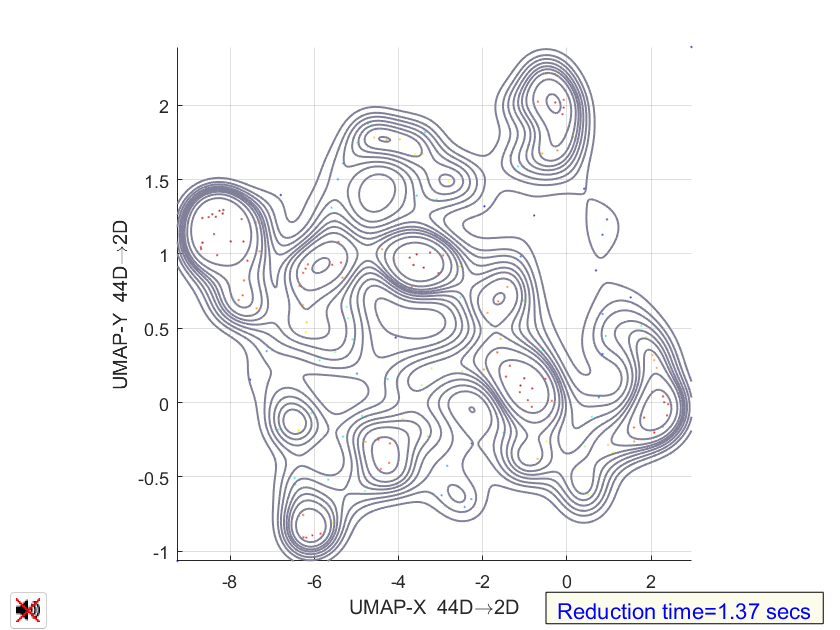

UMAP reduction finished (cost 1.73 secs)
 Finished basic (ub) reduction


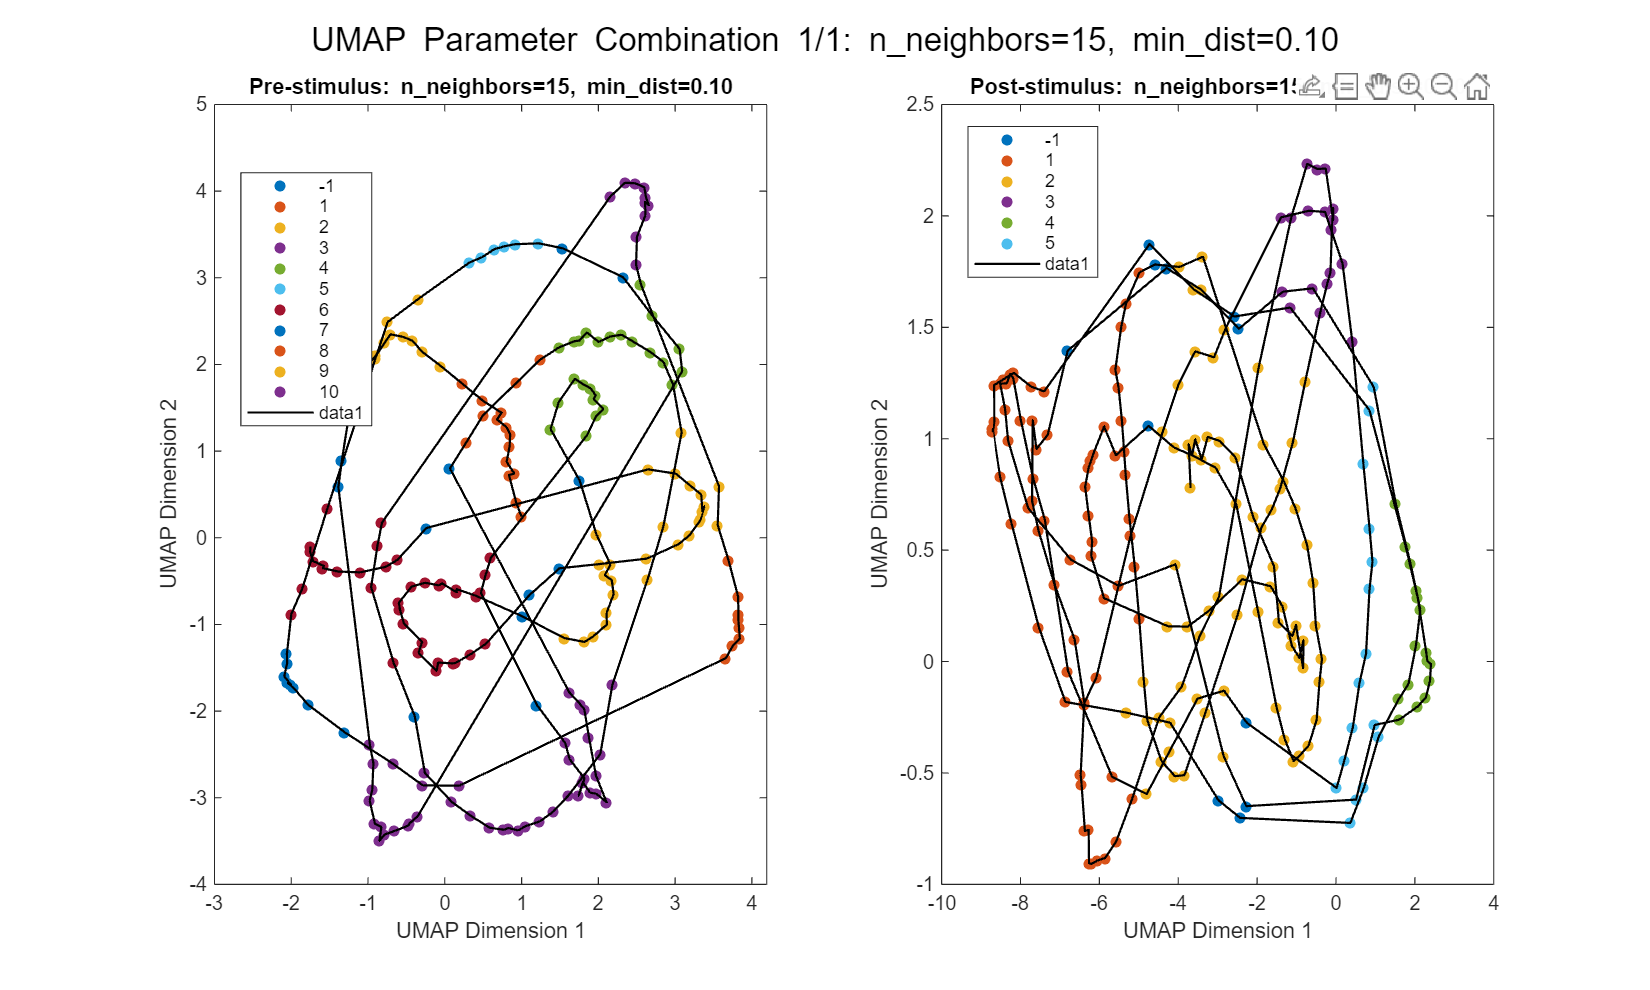

% Time factor analysis using UMAP
% First, make sure you have the UMAP MATLAB package installed
% You can install it via: 
% https://www.mathworks.com/matlabcentral/fileexchange/71902-uniform-manifold-approximation-and-projection-umap

% Define parameter combinations to test
% n_neighbors_values = [50, 70, 150];
% min_dist_values = [0.1, 0.5, 0.7]; % Changed 1.0 to 0.8 to avoid potential boundary issues
n_neighbors_values = 15;
min_dist_values = 0.1; %

% Number of combinations
num_combinations = length(n_neighbors_values) * length(min_dist_values);

% Create structure to store results
results = struct('n_neighbors', {}, 'min_dist', {}, ...
                'umap_time_pre', {}, 'umap_time_post', {}, ...
                'pre_clusters', {}, 'post_clusters', {}, ...
                'status', {});

% Set consistent random seed for reproducibility
rng(42);

% Prepare figure for visualization
figure('Position', [100, 100, 1200, 800]);

% Counter for subplot positions
combo_idx = 1;

% Loop through all parameter combinations
for i = 1:length(n_neighbors_values)
    for j = 1:length(min_dist_values)
        % Current parameter set
        curr_n_neighbors = n_neighbors_values(i);
        curr_min_dist = min_dist_values(j);
        
        % Initialize current result entry
        curr_result = struct('n_neighbors', curr_n_neighbors, ...
                           'min_dist', curr_min_dist, ...
                           'umap_time_pre', [], 'umap_time_post', [], ...
                           'pre_clusters', [], 'post_clusters', [], ...
                           'status', 'pending');
        
        % Display current parameter combination
        fprintf('Testing n_neighbors=%d, min_dist=%.2f (%d/%d)\n', ...
                curr_n_neighbors, curr_min_dist, num_combinations);
        
        % Try running UMAP with current parameters
        try
            % Run UMAP on pre-condition trial factors
            [umap_time_pre, umap_time_params] = run_umap(U_pre{2}, 'n_neighbors', curr_n_neighbors, ...
                                             'min_dist', curr_min_dist, ...
                                             'n_components', 2, ...
                                             'seed', 42);
            
            % Run UMAP on post-condition trial factors
            [umap_time_post, ~] = run_umap(U_post{2}, 'n_neighbors', curr_n_neighbors, ...
                                    'min_dist', curr_min_dist, ...
                                    'n_components', 2, ...
                                    'seed', 42);
            
            % Store UMAP results
            curr_result.umap_time_pre = umap_time_pre;
            curr_result.umap_time_post = umap_time_post;
            
            % Apply DBSCAN clustering
            epsilon = 0.5;  % You might want to adjust this for each parameter set
            minPts = 5;
            
            curr_result.pre_clusters = dbscan(umap_time_pre, epsilon, minPts);
            curr_result.post_clusters = dbscan(umap_time_post, epsilon, minPts);
            
            % Mark as successful
            curr_result.status = 'success';
            
           % Create a new figure for this parameter combination
            fig = figure('Position', [100, 100, 1000, 600]);
            
            % Pre-stimulus plot
            subplot(1, 2, 1);
            gscatter(umap_time_pre(:,1), umap_time_pre(:,2), curr_result.pre_clusters);
            hold on;
            plot(umap_time_pre(:,1), umap_time_pre(:,2), 'k-', 'LineWidth', 1);
            title(sprintf('Pre-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            hold off;

            % Post-stimulus plot
            subplot(1, 2, 2);
            gscatter(umap_time_post(:,1), umap_time_post(:,2), curr_result.post_clusters);
            hold on;
            plot(umap_time_post(:,1), umap_time_post(:,2), 'k-', 'LineWidth', 1);
            title(sprintf('Post-stimulus: n\\_neighbors=%d, min\\_dist=%.2f', curr_n_neighbors, curr_min_dist));
            xlabel('UMAP Dimension 1');
            ylabel('UMAP Dimension 2');
            hold off;

            % Add overall title
            sgtitle(sprintf('UMAP Parameter Combination %d/%d: n\\_neighbors=%d, min\\_dist=%.2f', ...
                combo_idx, num_combinations, curr_n_neighbors, curr_min_dist));
            
            % % Save the figure
            % fig_filename = sprintf('umap_params_n%d_d%.2f.png', curr_n_neighbors, curr_min_dist);
            % saveas(fig, fig_filename);
            % 
            % % Optional: close the figure if you don't want too many open at once
            % close(fig);
            
        catch e
            % Handle errors
            fprintf('Error with n_neighbors=%d, min_dist=%.2f: %s\n', ...
                    curr_n_neighbors, curr_min_dist, e.message);
            curr_result.status = sprintf('error: %s', e.message);
        end
        
        % Store current result
        results(end+1) = curr_result;
        
        % Increment combination counter
        combo_idx = combo_idx + 1;
    end
end


% Save all results to a MAT file
% save('umap_time_parameter_exploration.mat', 'results');

% Display summary
fprintf('\nParameter Testing Summary:\n');


Parameter Testing Summary:


fprintf('------------------------\n');

------------------------


for i = 1:length(results)
    fprintf('n_neighbors=%d, min_dist=%.2f: %s\n', ...
            results(i).n_neighbors, results(i).min_dist, results(i).status);
end

n_neighbors=15, min_dist=0.10: success


function score = calculate_neighborhood_preservation(orig_data, embedded_data, k)
    % Get the k nearest neighbors in original space
    [~, orig_idx] = pdist2(orig_data, orig_data, 'euclidean', 'Smallest', k+1);
    orig_idx = orig_idx(2:end, :)'; % Remove self and transpose
    
    % Get the k nearest neighbors in embedded space
    [~, emb_idx] = pdist2(embedded_data, embedded_data, 'euclidean', 'Smallest', k+1);
    emb_idx = emb_idx(2:end, :)'; % Remove self and transpose
    
    % Calculate overlap between neighborhoods
    overlap = 0;
    for i = 1:size(orig_data, 1)
        overlap = overlap + length(intersect(orig_idx(i,:), emb_idx(i,:)));
    end
    
    % Return average percentage of preserved neighbors
    score = overlap / (k * size(orig_data, 1));
end